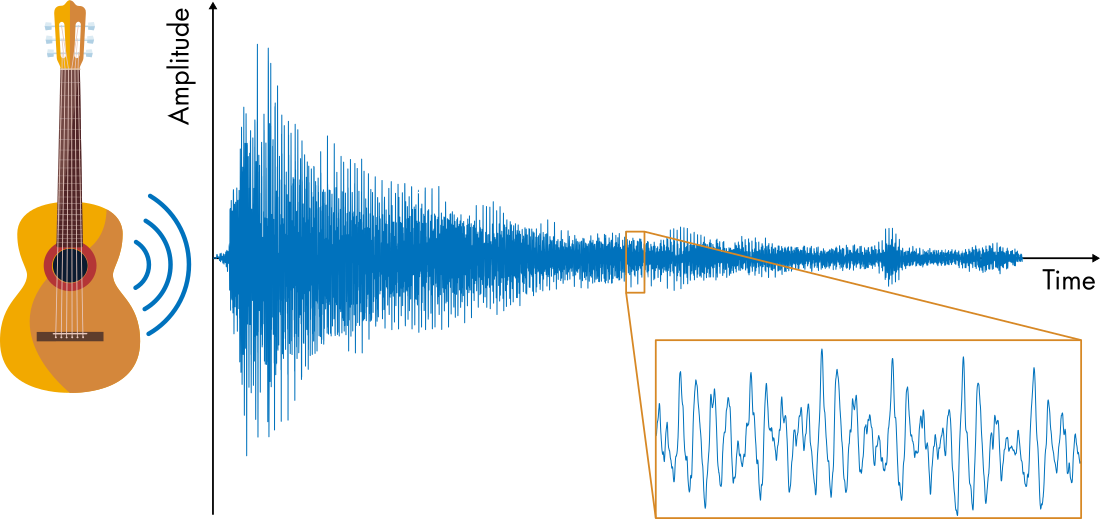

When a guitar is strummed, the vibration of the strings and guitar body emits a pressure wave. You can record that wave with a microphone, but analyzing it can daunting. There's just so much going on. However, zoom in on the audio signal, and you'll find a series of repeating patterns. Analyze the signal in the frequency domain, and you'll uncover what's really going on here.

# Fourier Series

**Learning Goals**

- Compare signals in the time and frequency domains.

- Analyze audio signals in the frequency domain.

- Visualize Fourier series modes.

- Describe how phase shift is represented in a Fourier series.

- Compute the Fourier series of a periodic function.

- Discuss magnitude and phase.

## The Frequency Domain

Fourier analysis is all about taking signals from the time domain (or spatial domain) and analyzing them in the *frequency domain*. 

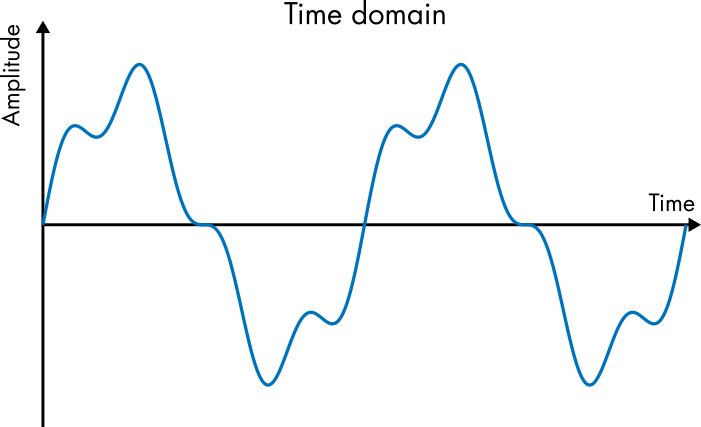      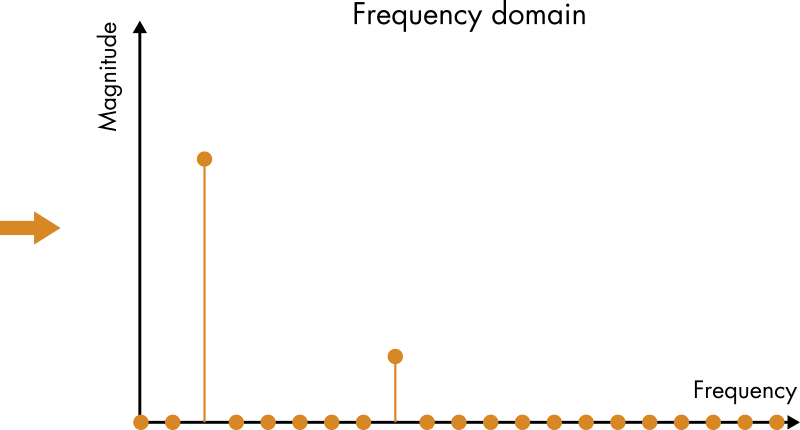

*A signal in the time and frequency domains. While the signal has a a lot going on in the time domain, it actually a simple sum of two sine functions, as illustrated in the frequency domain.*

Each frequency present in a signal creates a peak in the frequency domain. The stronger that frequency is in the signal, the larger the peak is in the frequency domain. 

### A Single Sine Function

Consider the function 


$$y(t) = A \sin( 2\pi f t)$$


This sine function has a frequency of $f$ Hz. Suppose that $f = 220$ Hz. When represented in the time domain, the function is plotted against time producing the usual sine curve. In the frequency domain, the function is represented by a single peak at 220 Hz. The amplitude $A$ determines the height of the peak in the frequency domain.

The plot illustrates $y$ in both the time and frequency domains. 

- What happens in each plot when you increase $f$, the frequency of the sine curve?

- How do the plots change when the amplitude $A$ is increased?

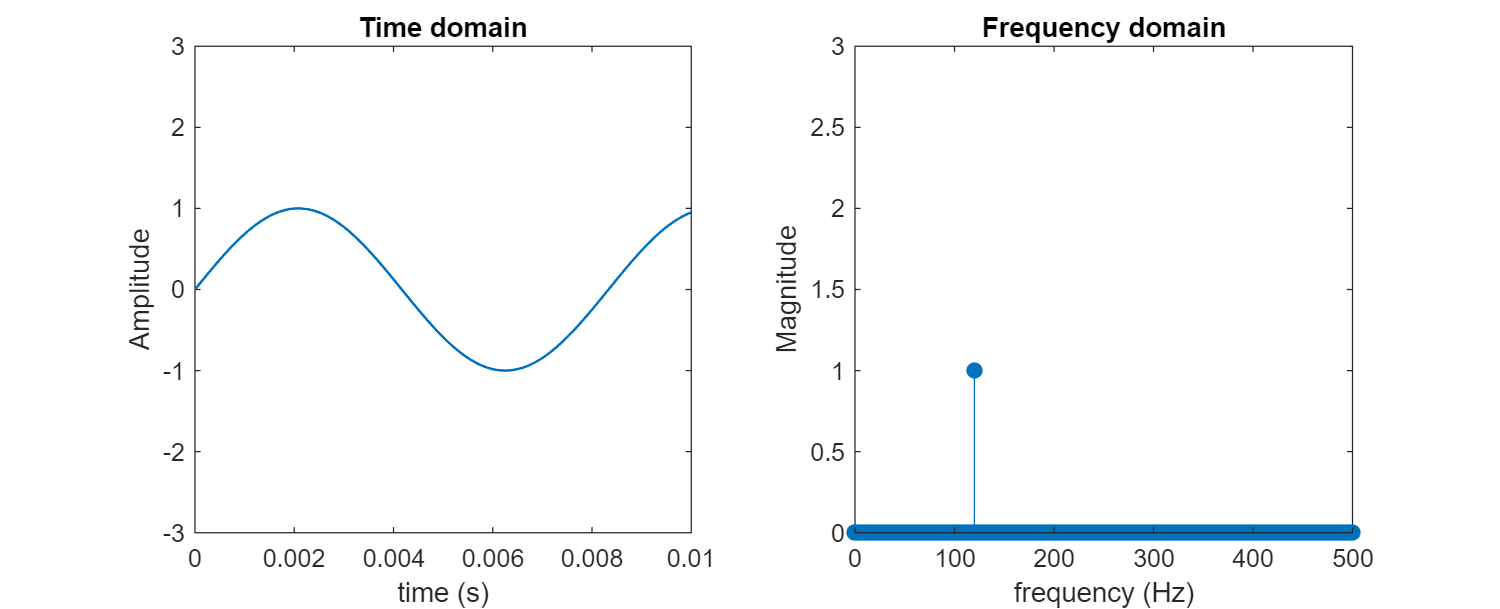

f = 120;
A = 1;
plotSingleSine(A, f); % Helper function that generates the plots

    **Activity. **A 220 Hz signal is special; it represents a "perfect" A note. You can listen to the 220 Hz signal by (1) generating the sine curve and (2) playing it as an audio signal.

**Task 1. **The time variable `t` has been created for you. Using `t`, create a signal, `y`, that is a sine wave with a frequency of 220 Hz with an amplitude $A = 1$. 

Fs = 44.1e3; % Audio sample rate
t = 0:1/Fs:1; % 1 second time variable
% Create your signal y here
y = sin(2*pi*220*t);

**Task 2.** Call the [`soundsc`](https://www.mathworks.com/help/matlab/ref/soundsc.html) function to play the audio signal using the syntax

where `y` is the signal and `Fs` is the sample rate. Then, run the section to play `y` as an audio signal.

% This code will play the audio signal
soundsc(y,Fs)

**Task 3. **If you divide or multiply the frequency by 2, you land on the same note, but an octave higher or lower. Try adjusting the frequency to 110 Hz to listen to A note one octave lower.

### **A Real Signal**

The pure 220 Hz note probably did not sound very appealing. Sounds generated by musical instruments tend to have several complementary frequencies (known as harmonics) that create a richer sound. Listen to the guitar note played below.

[yGuitar,FsGuitar] = audioread("Anote.mp3");
soundsc(yGuitar,FsGuitar)

You can analyze the guitar note in the time domain by plotting the audio signal. Below, about 10 miliseconds of the signal is plotted. 

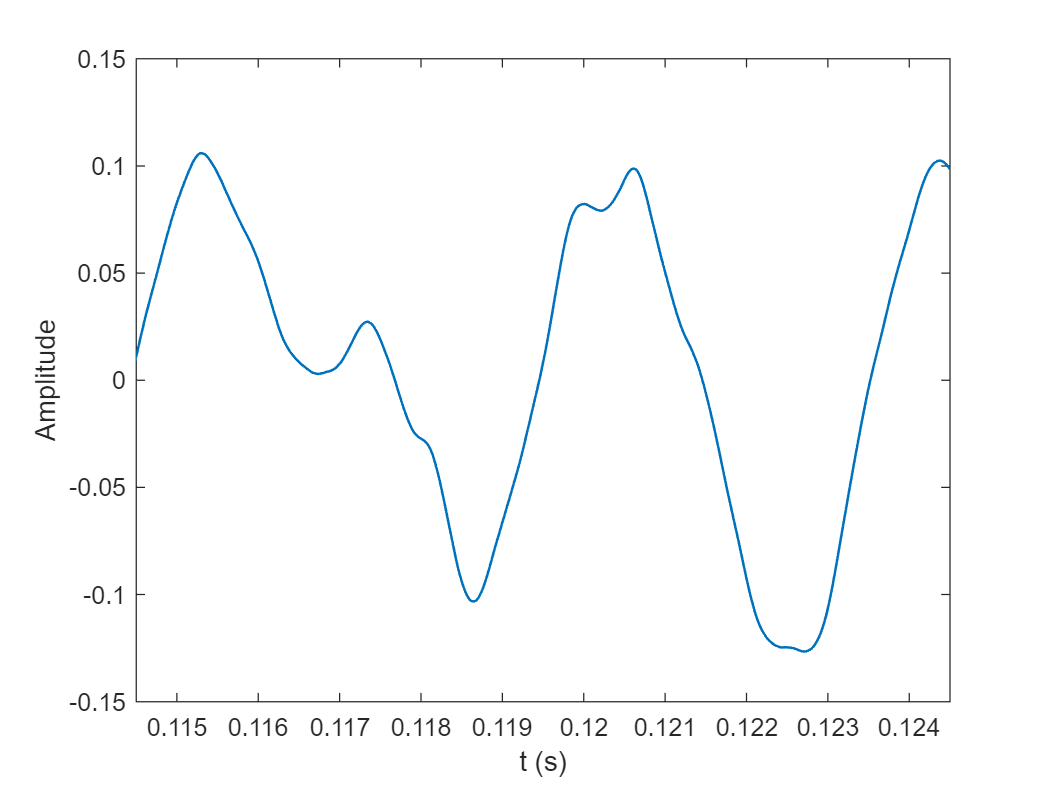

tGuitar = (1:length(yGuitar))/FsGuitar; % Time variable
% Generate the plot
figure 
plot(tGuitar,yGuitar(:,1),"Linewidth",1)
xlim([0.1145,0.1245])
xlabel("t (s)")
ylabel("Amplitude")

**  Reflect.** 

- Compare this signal to the pure sine signal plotted in the previous activity. Can you pick out the dominant frequency(ies) in the guitar audio signal?

- In the frequency domain, how many peaks would you expect to see for the guitar signal?

 **Exercise. **Clearly, there's more to the guitar A note than the single root frequency. Consider the function


$$y(t) = b_1 \sin( 2\pi f_1 t) + b_2 \sin( 2\pi f_2 t) + b_3 \sin( 2\pi f_3 t) $$


where $b_i$ is the amplitude of component and $f_i$ is its frequency in Hz. Follow the steps below to design $y$ so that it sounds like the recording (well, as much as possible). The root frequency of the guitar's A note is 110 Hz, the first harmonic is 220 Hz, and the second harmonic is 330 Hz. Use these values for the frequencies of the signals. You can use the variable `t` to help you create your signal.

**Task 1. **Define the signal, `y`, in MATLAB.

Fs = 44.1e3; % Audio sample rate
t = 0:1/Fs:1; % 1 second time variable
% Define the coefficients b1, b2, and b3
b1 = 0.5;
b2 = 2;
b3 = 0.3;
% Define the frequencies f1, f2, and f3 in Hz
f1 = 110;
f2 = 220;
f3 = 330;
% Create the signal y
y = b1*sin(2*pi*f1*t) + b2*sin(2*pi*f2*t) + b3*sin(2*pi*f3*t);

**Task 2. **Plot the signal `y` against `t` using the [`plot`](https://www.mathworks.com/help/matlab/ref/plot.html) function. Adjust the x-axis limits to `[0,0.01]` using the [`xlim`](https://www.mathworks.com/help/matlab/ref/xlim.html) function.

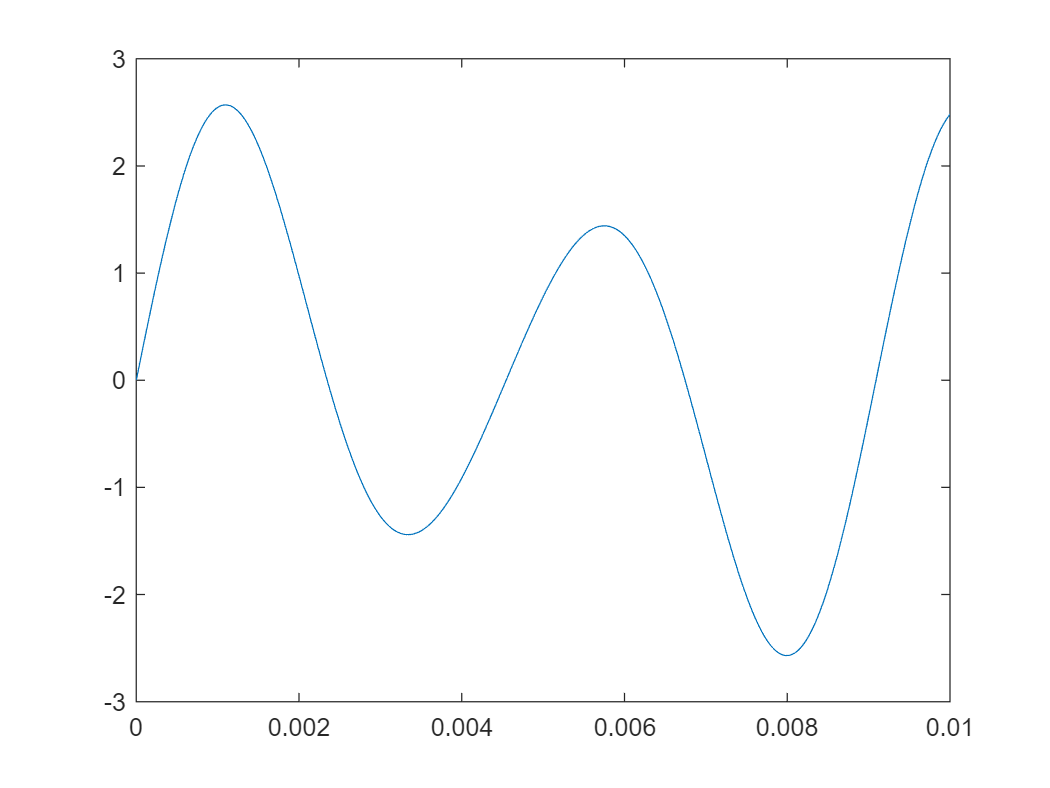

plot(t,y)
xlim([0,0.01])

**Task 3.** Use the [`soundsc`](https://www.mathworks.com/help/matlab/ref/soundsc.html) function to play your signal. 

soundsc(y,Fs)

**Task 4. **Adjust the coefficients `bi` so that the signal better replicates the guitar signal in both the plot and the sound. Note that it will never match perfectly, so only make 3 or 4 adjustments.

**  Reflect.** 

- Which frequency has the greatest amplitude (110 Hz, 220 Hz, or 330 Hz)?

- What is missing from $y(t)$ that is needed to reproduce the guitar signal?

## Fourier Sine and Cosine Series

To accurately reproduce a periodic real-world signal, it is often the case that more than 3 frequencies are required. Fourier series reproduce **periodic** signals using an infinite number of frequencies (in theory). In practical signal processing, only a finite number of frequencies are used. The *Fourier sine series *is an infinite sum of sine functions:


$$f(t) = \sum_{n=1}^\infty b_n \sin \left( \frac{ n \pi } {L}  t \right)$$


$L$ is a parameter the determines the periodicity of the function $f$, which has period $2L$. Each term in the sum is known as a *Fourier* *mode*. For example, the fundamental mode (with $n = 1$) is


$$f_1 = \sin \left( \frac{\pi}{L} t \right)$$
 

The first coefficient $b_1$ determines how strongly this mode is represented in the overall sum.

    **Activity. **In this activity you will build several functions using the Sine and Cosine Series app. Click the link to open the app, then complete the tasks listed below.

[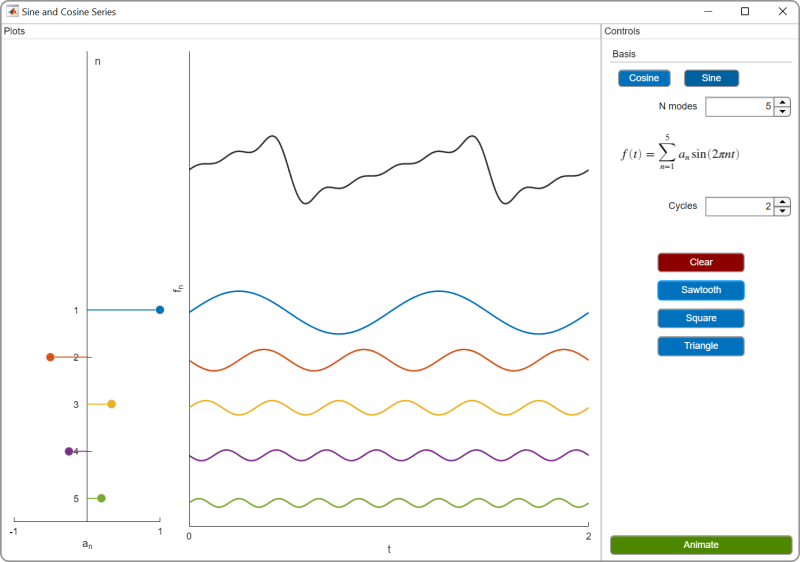](matlab: SinCosSeries)

[SinCosSeries.mlapp](matlab: SinCosSeries)

**Task 1. **Set the Fourier basis to Sine.

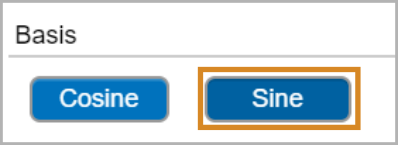

**Task 2. **Create the signal shown. To do so, click and drag the Fourier coefficients so that $a_1 = 1$ and $a_3 = 3$. These are located on the stem plot on the left.

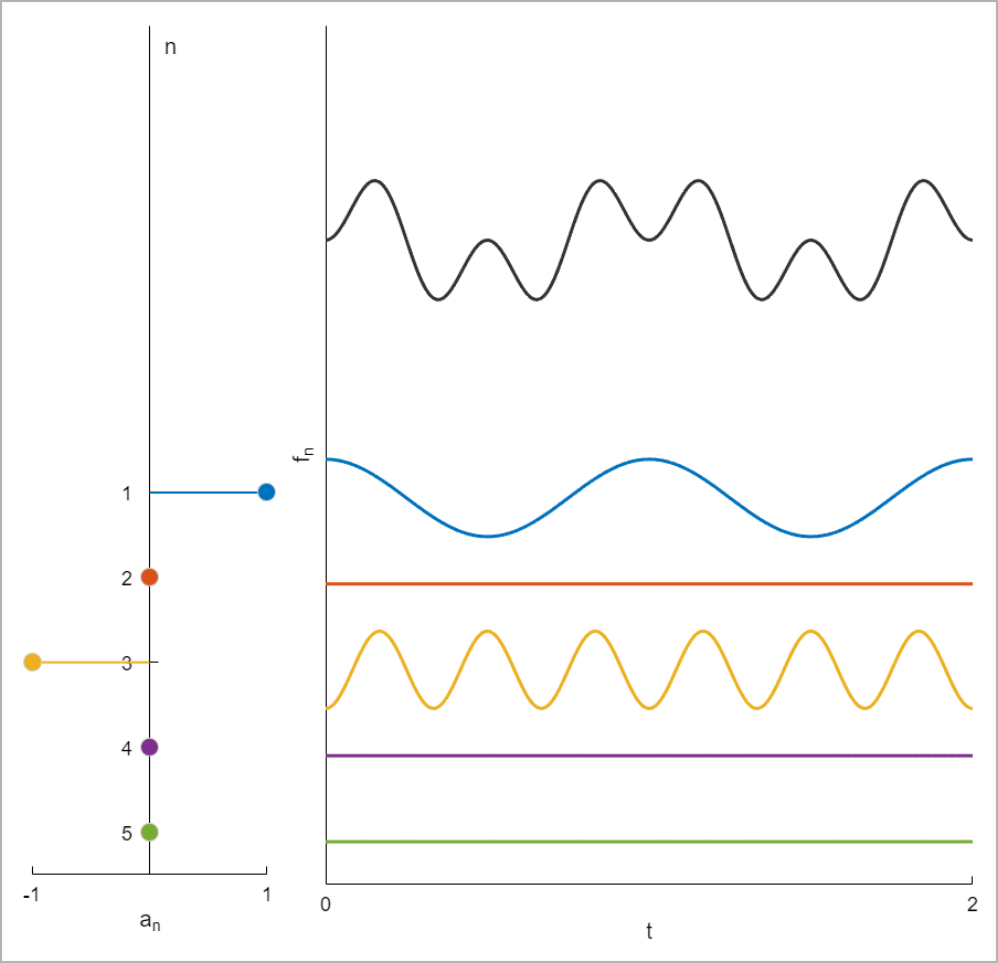

**Task 3. **Click the animate button to illustrate how the components are added to build the overall function.

**Task 4. **Adjust the Fourier coefficients to (approximately) $a_1 = 1$, $a_2 = 0.5$, $a_3 = 0.25$, $a_4 = 0.125$, $a_5 = 0.0625$ and animate the plot. What waveform is produced?

**Task 5. **Recreate the waveforms pictured below by adjusting the Fourier coefficients (use a Sine basis).

(a) 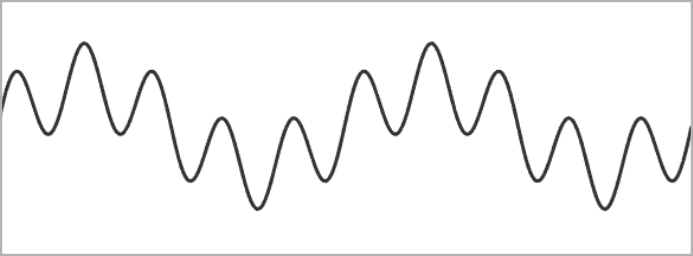

(b) 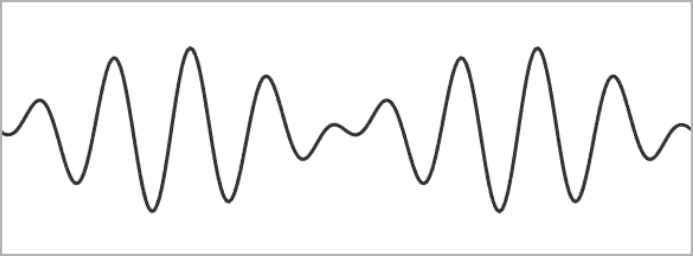

## Fourier Series

The Fourier sine series contains infinitely many frequencies. This allows the series to produce many different waveforms. However, all frequencies produced using only sine modes will have zero *phase*. 

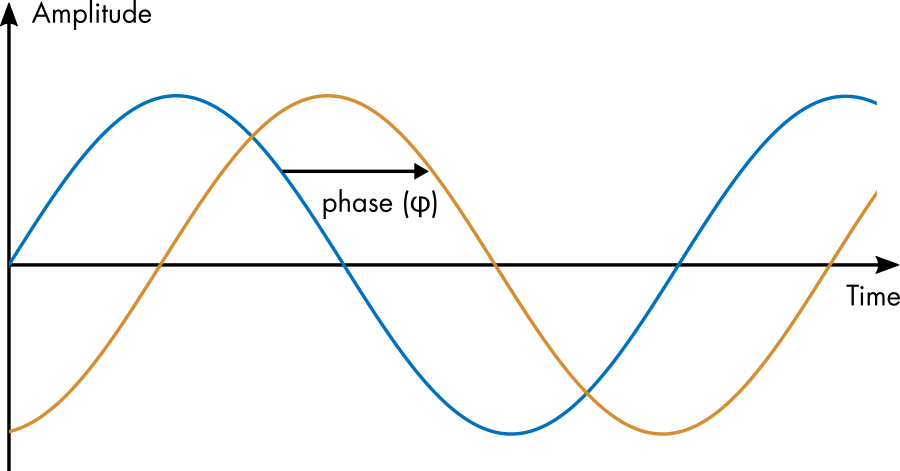

*The phase or phase shift of a signal is how far it has been shifted horizontally. *

Real signals do not typically have zero phase, and so the Fourer sine series is insufficient to represent them. However, adding a cosine series allows you to produce signals with any phase. 

### **Definition**

One common definition for the Fourier series is the combination of cosine and sine series:


$$f(t) = \frac{a_0}{2}  + \sum_{n=1}^\infty a_n \cos\left( \frac{ n \pi } {L}  t \right) + b_n \sin \left( \frac{ n \pi } {L}  t \right)$$


With this addition, there are now two sets of coefficients: the cosine series coefficients $a_n$ and the sine coefficients $b_n$. The sine terms have a phase of $0^\circ$ while the cosine signals have a phase of $90^\circ$ (assuming that zero phase corresponds to a sine signal). If you combine a cosine and sine signal with the same frequency, it produces a phase shifted signal:


$$a \cos (\omega t) + b \sin( \omega t) = c \sin( \omega t  -  \phi)$$


where the phase shift is determined by the ratio of the coefficients $a$ and $b$. 

    **Activity. **Create phase shifted signals using Fourier series by completing the tasks below.

**Task 1. **Open the Interactive Fourier Series app.

[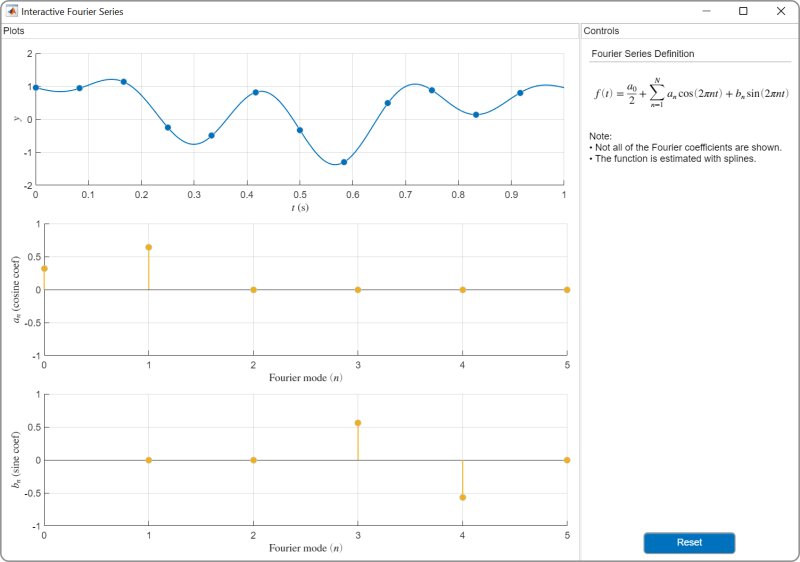](matlab: InteractiveFourierSeries)

[InteractiveFourierSeries.mlapp](matlab: InteractiveFourierSeries)

In the app, $L = 1/2$ by default, so the the period of the Fourier series is 1 s. This implies that the fundamental mode with index $n = 1$ has a frequency of 1 Hz. To adjust the mode coefficients, click and drag the yellow circles. For this exercise, do not drag the blue circles.

**Task 2. **Adjust the Fourier coefficients to create a 1 Hz signal with zero phase ($\phi = 0 ^\circ$) (relative to a sine function).

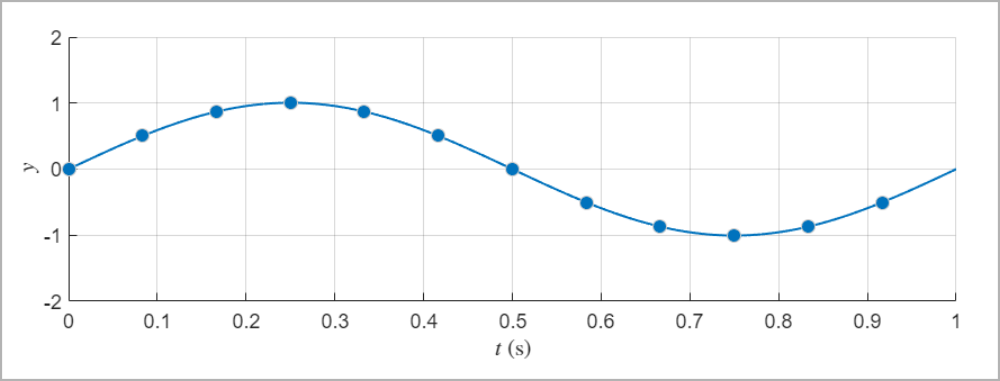

**Task 3.** Adjust the Fourier coefficients to create a 2 Hz signal with a phase shift of $\phi = 90 ^\circ$ (relative to a sine function).

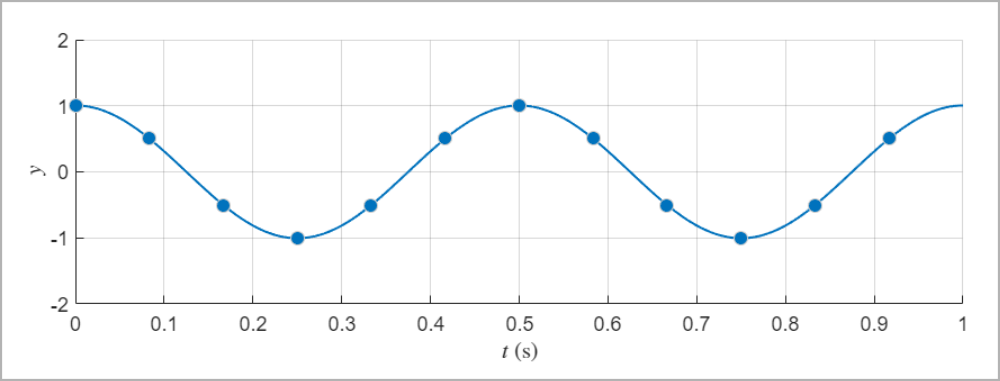

**Task 4.** A 1 Hz signal with a phase shift of $\phi = 45^\circ$ (relative to a sine function).

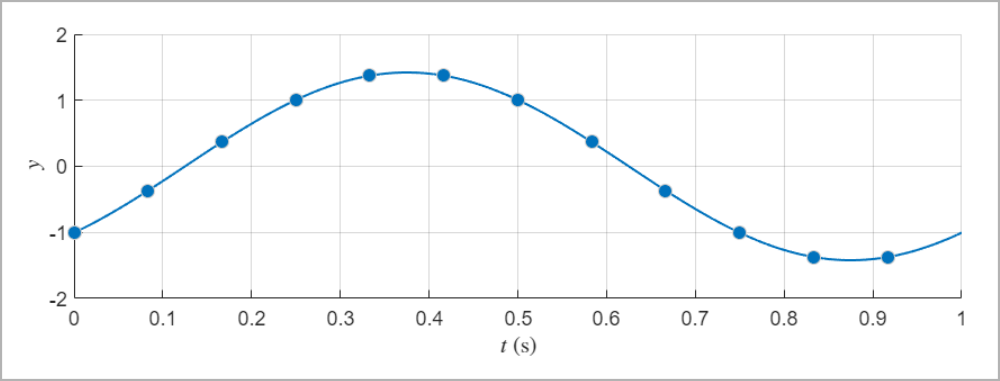

## Solving for Fourier Series Coefficients

The guitar A note audio signal clearly has at least 3 frequencies.

**Task.** Run this section to show the guitar signal.

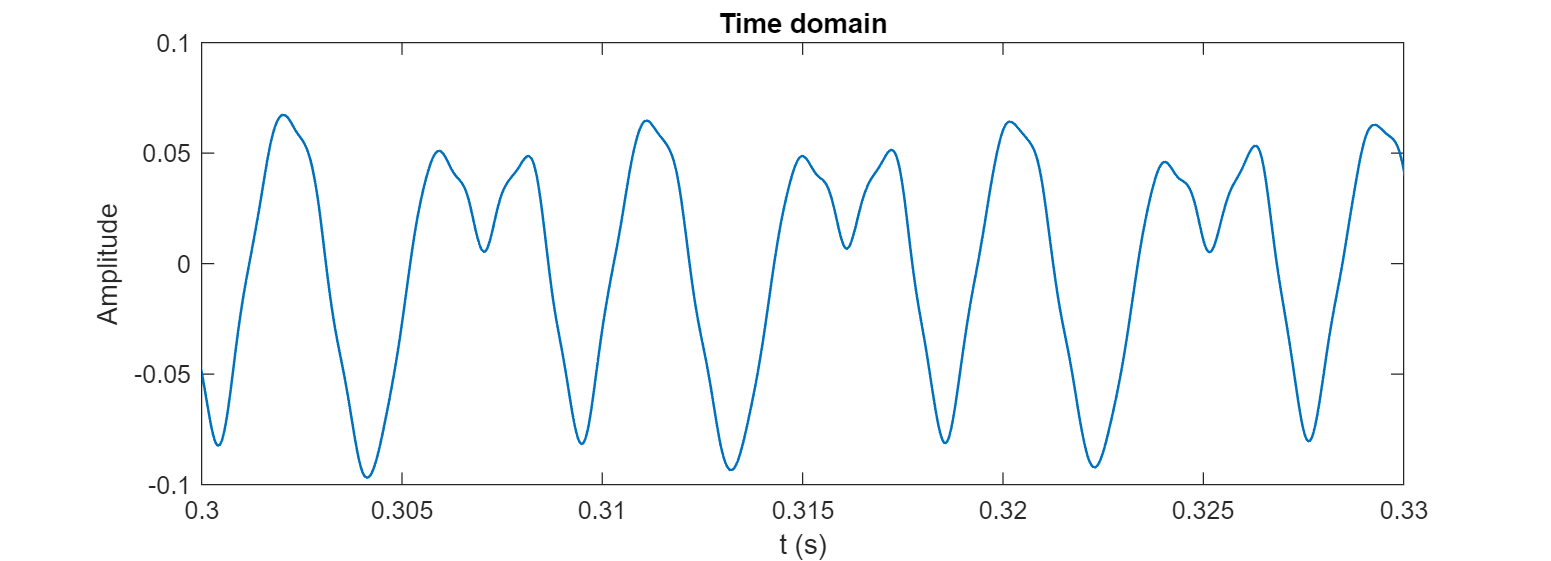

% This code plays the guitar sound and plots part of the signal
[yGuitar,FsGuitar] = audioread("Anote.mp3");
soundsc(yGuitar,FsGuitar)
plotGuitarSignal(yGuitar,FsGuitar,[0.3,0.33])

But what are the frequencies and how strongly is each represented? In other words, what does the guitar audio signal look like in the frequency domain?

### Fourier Coefficient Formulas

In the previous activities, you adjusted the Fourier coefficients by hand. Fortunately, this isn't necessary to identify the Fourier series coefficients of a given signal. You can identify the coefficients of a $2L$ periodic function using two formulas:


$$a_n = \frac{1}{L} \int_{-L}^{L} y(t) \cos \left( \frac{ n \pi }{L} t \right) dt$$



$$b_n = \frac{1}{L} \int_{-L}^{L} y(t) \sin\left( \frac{ n \pi }{L} t \right) dt$$


These integrals calculate the weight of the $n^{th}$ mode required to match the given signal, $y(t)$. These expressions are independent because the basis functions (the sines and cosines) are orthogonal to each other.

The plot below shows the Fourier modes of the guitar signal estimated using the integral formulas and the trapezoid rule.

**Task.** Run the section to see the guitar A note in the frequency domain.

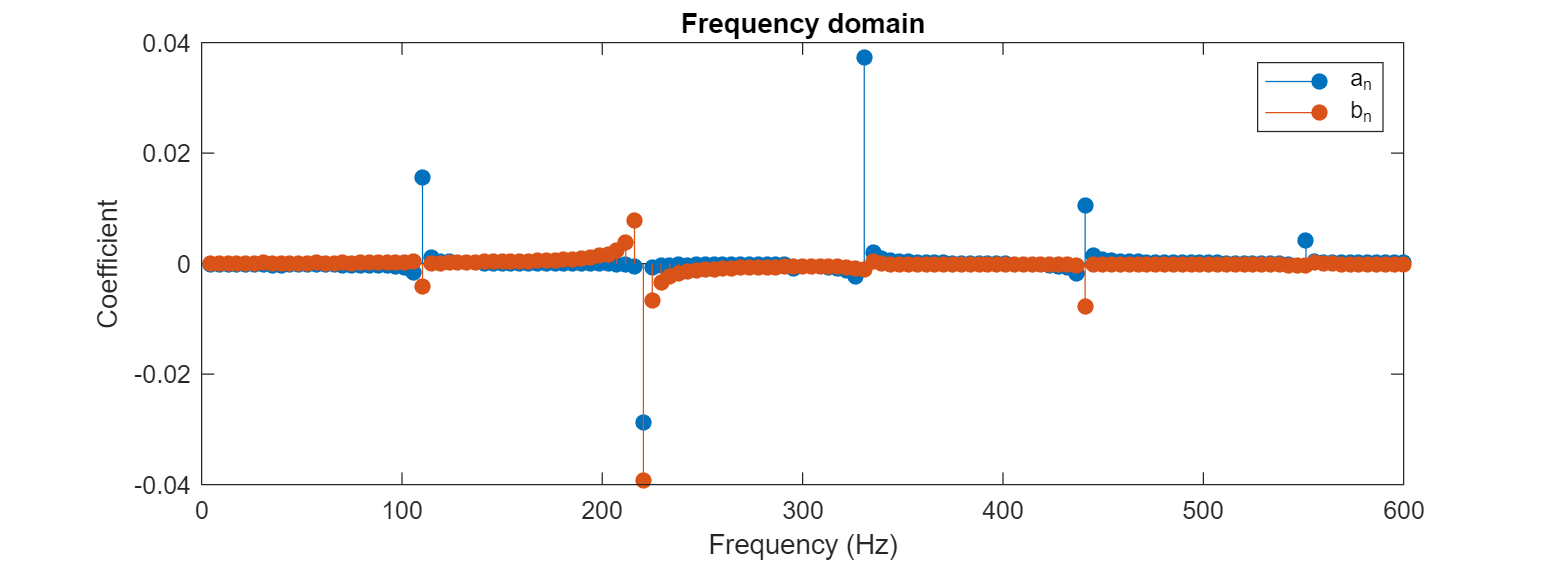

% Helper functions that estimate and plot the Fouier coefficients
[freq,a,b] = computeGuitarFourierCoef(yGuitar,FsGuitar);
plotGuitarCoef(freq,a,b)

Try clicking on a peak to create a data tip. You can use this to identify the frequency of a mode.

**  Reflect.** 

- Which frequency is dominant?

- Are the dominant frequencies purely sine or cosine? 

- Based on the observed coefficients, can you make any general statements about the phase of each mode?

## **Magnitude and Phase Fourier Series**

### **Magnitude**

From the frequency domain plot above, it may appear that the 330 Hz signal has nearly equal amplitude to the 220 Hz signal. However, this is not actually the case, because the magnitude of a particular frequency is a combination of both coefficients. Specifically, the magnitude of the $n^{th}$ mode is


$$A_n = \sqrt{ {a_n}^2 + {b_n}^2 }$$


 **Exercise.**

**Task 1.** Ensure that the previous section was run to produce the variables: `freq`, `a`, and `b`. 

**Task 2. **Compute the magnitude of the coefficients ($A_n$) from the vectors `a` and `b` using the formula and store the result in `A`. 

  **Pro-tip.** Perform element-wise operations on vectors by prepending a period character. For example, to compute the square of the coefficient vector `a`, use `a.^2`.

% Compute A here
% A should be a vector that contains the magnitudes
A = sqrt(a.^2 + b.^2);

**Task 3. **Plot the magnitudes in `A` against the frequencies in `freq` using a [`stem`](https://www.mathworks.com/help/matlab/ref/stem.html) plot. Set the frequency limits to [0,600] using the [`xlim`](https://www.mathworks.com/help/matlab/ref/xlim.html) function.

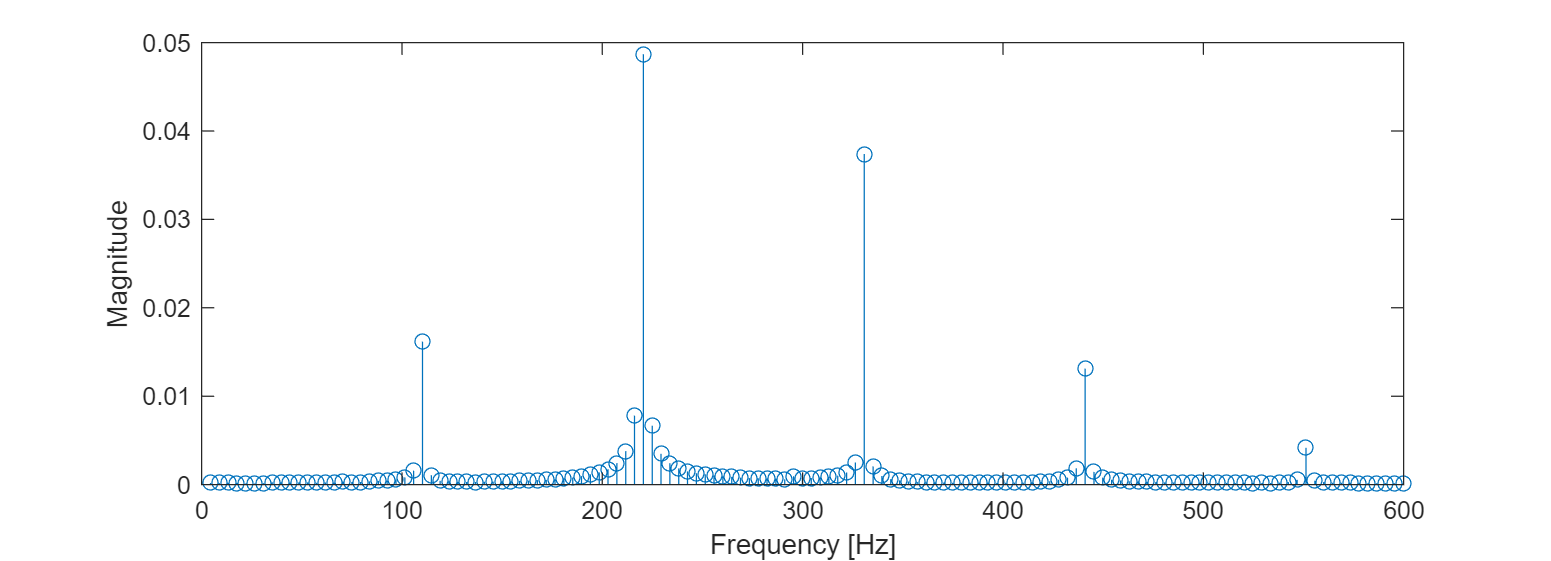

stem(freq,A)
xlim([0,600])
ylabel("Magnitude")
xlabel("Frequency [Hz]")

**  Reflect.** 

- Which frequency is dominant?

- The fundamental frequency of the guitar A note is 110 Hz. Does this plot make sense for the guitar A note?

### **Magnitude and Phase Plots**

The frequency domain can be visualized by plotting the coefficients $a_n$  and $b_n$ as done in the previous sections. An alternative way to picture the frequency domain is in terms of magnitude and phase.

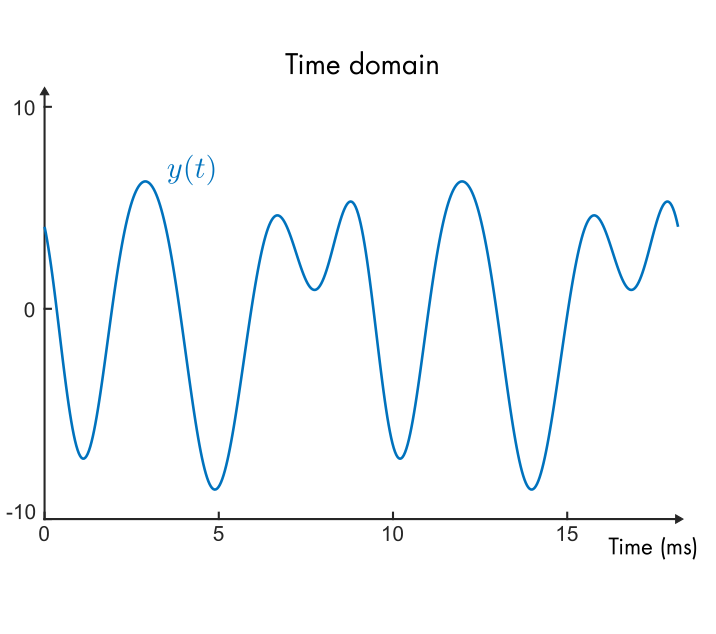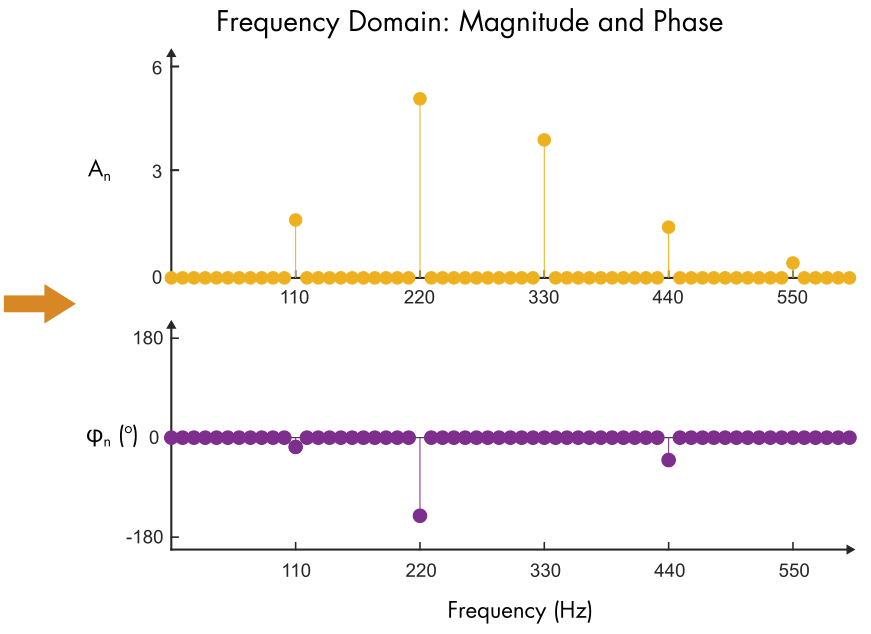

*The 5 main modes of the guitar A note* *signal in the time domain and frequency domain. *

*Here, the frequency domain is plotted using magnitude and phase.*

This plot is often more useful than the plot of $a_n$ and $b_n$ because it clearly illustrates two intuitive features of each mode:

- **magnitude**: the strength of the mode

- **phase**: how far the mode has been shifted along the time axis

    **Activity. **In this activity, you will compare the two discussed frequency domain representations: the sine-cosine representation in terms of the coefficients $a_n$ and $b_n$ and the magnitude-phase representation in terms of the magnitude $A_n$ and the phase $\phi_n$.

**Task 1. **Run the Fourier Series: Magnitude and Phase app

[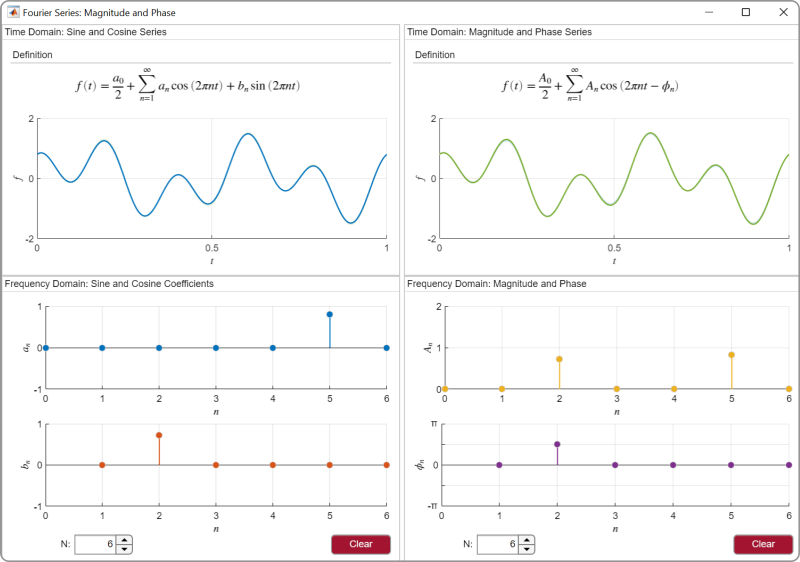](matlab: run MagnitudePhase.mlapp)

[`MagnitudePhase.mlapp`](matlab: run MagnitudePhase.mlapp)

Notice that the first pane (on the left) shows the sine-cosine version of the frequency domain ($a_n$ and $b_n$). The right plane uses magnitude ($A_n$) and phase ($\phi_n$) instead.

**Task 2. **Set $a_1 = -1$ and leave all other $a_n, \ b_n = 0$. You can click and drag the stem plot to adjust the coefficients. The first time-series plot should appear as shown below.

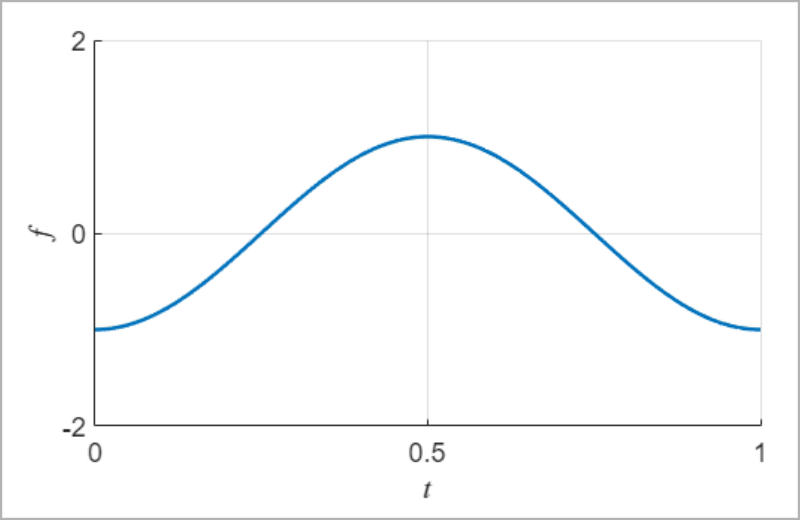

**Task 3.** Reproduce the same plot by adjusting the magnitude ($A_n$) and phase ($\phi_n$) in the second pane.

**Task 3.** Adjust the frequency domain coefficients $a_n$ and $b_n$ in the first pane to create the function. 


$$f(t) = 0.5 - \sin(4 \pi t) + \cos( 4 \pi t)$$


If correct, you should see the time series plotted below.

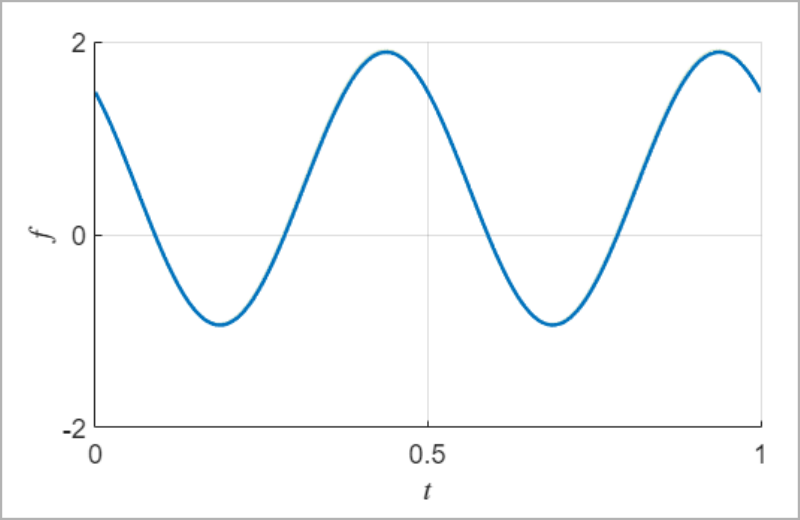

**Task 4. **Reproduce the same time series function $f(t)$ using the second pane (on the right) by adjusting the magnitude $A_n$ and phase $\phi_n$ parameters. If correct, the second time series plot should match the one from **Task 2**.

**Hint**: You only need to adjust the $n = 0$ and $n = 2$ mode parameters.

**Task 5. **Repeat **Tasks 3** and **4 **for the function 


$$f(t) = \sin(2 \pi t) + \cos( 2 \pi t) + 0.5 \sin (12 \pi t)$$


### Definition

In the last activity, you adjusted the magnitude and phase of the Fourier series. While you only saw the plots, you were actually adjusting the parameters of this standard definition:


$$f(t) = \frac{A_0}{2} +  \sum_{n=1}^{\infty} A_n \cos\left( \frac{ n \pi } {L}  t - \phi_n \right)$$


This definition is related to the sine-cosine definiton through

$A_n = \sqrt{a_n^2 + b_n^2}$     and    $\phi_n = \text{atan2}\left( b_n,a_n\right)$

Note that phase angle is computed using the two-argument arctangent. In MATLAB, this is implented in the function [`atan2`](https://www.mathworks.com/help/matlab/ref/atan2.html). 

**Helper Functions**

function plotSingleSine(A, f)
    % Time domain
    t = linspace(0,0.01,500);
    g = A*sin(2*pi*f*t);
    
    % Frequency domain
    freq = 0:500;
    ghat = zeros(1,501);
    ghat(f+1) = A;
    
    figure("position",[1,1,800,325])
    % Time domain plot
    subplot(1,2,1)
    plot(t,g,"linewidth",1)
    ylim([-3,3])
    title("Time domain")
    xlabel("time (s)")
    ylabel("Amplitude")
    
    % Frequency domain plot
    subplot(1,2,2)
    stem(freq,ghat,"filled")
    ylim([0,3])
    title("Frequency domain")
    xlabel("frequency (Hz)")
    ylabel("Magnitude")
end

function plotGuitarSignal(yGuitar,FsGuitar,timeLimits)
    tGuitar = (1:length(yGuitar))/FsGuitar; % Time variable    
    % Generate the plot
    figure("position",[1,1,900,325]) 
    plot(tGuitar,yGuitar(:,1),"Linewidth",1)
    xlim(timeLimits)
    xlabel("t (s)")
    ylabel("Amplitude")
    title("Time domain")
end

function [freq,a,b] = computeGuitarFourierCoef(y,Fs)
    Nmodes = 1000;
    yc = y(1e4:2e4);
    
    tc = 1/Fs*(0:(length(yc)-1));
    L = tc(end)/2; % The domain is assumed to be 2L
    freq = (1:Nmodes)/(2*L); % Frequencies

    % Estimate coefficients using trapezoid rule
    a = zeros(1,Nmodes);
    b = zeros(1,Nmodes);
    a0 = 1/L*trapz(tc,yc);
    for n = 1:Nmodes
        a(n) = 1/L*trapz(tc,cos(n*pi/L*tc).*yc);
        b(n) = 1/L*trapz(tc,sin(n*pi/L*tc).*yc);
    end
end

function plotGuitarCoef(f,a,b)
    % Plot the result
    figure("position",[1,1,900,325])
    stem(f,a,"Filled")
    hold on
    stem(f,b,"Filled")
    hold off
    xlabel("Frequency (Hz)")
    ylabel("Coefficient")
    legend("a_n","b_n")
    title("Frequency domain")
    xlim([0,600])
end

